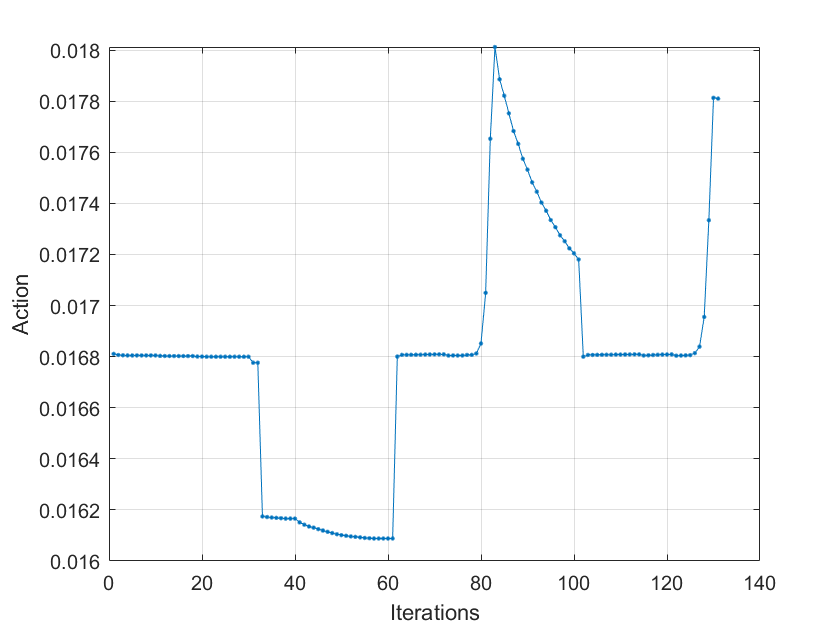


%Plot everything

[traj_pts,num_spec] = size(traj);

init_iter = 1;
tot_iter = size(S_arr,1);

%Action
figure()
plot(S_arr,'.-')
ylabel('Action')
xlabel('Iterations')
grid on

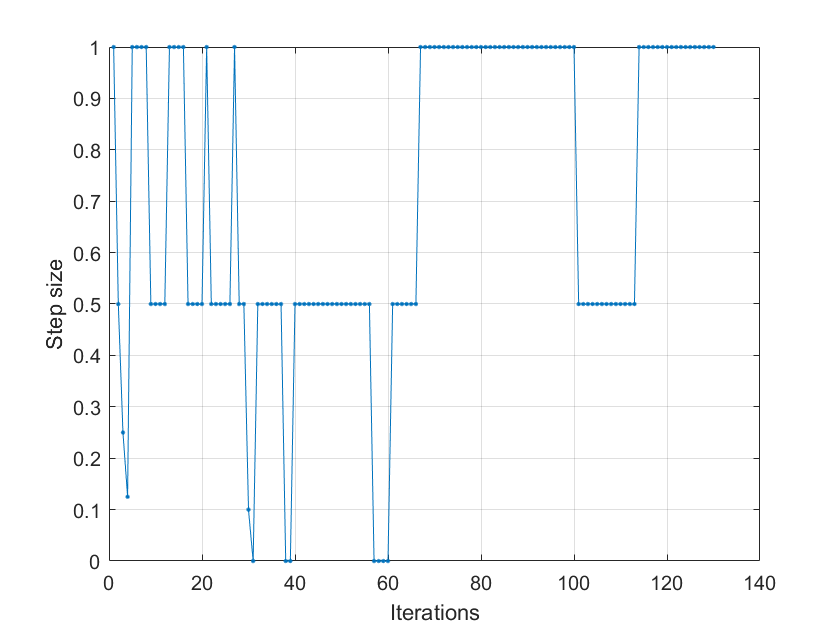


%epsilon-step size
figure()
plot(eps_arr,'.-')
ylabel('Step size')
xlabel('Iterations')
grid on

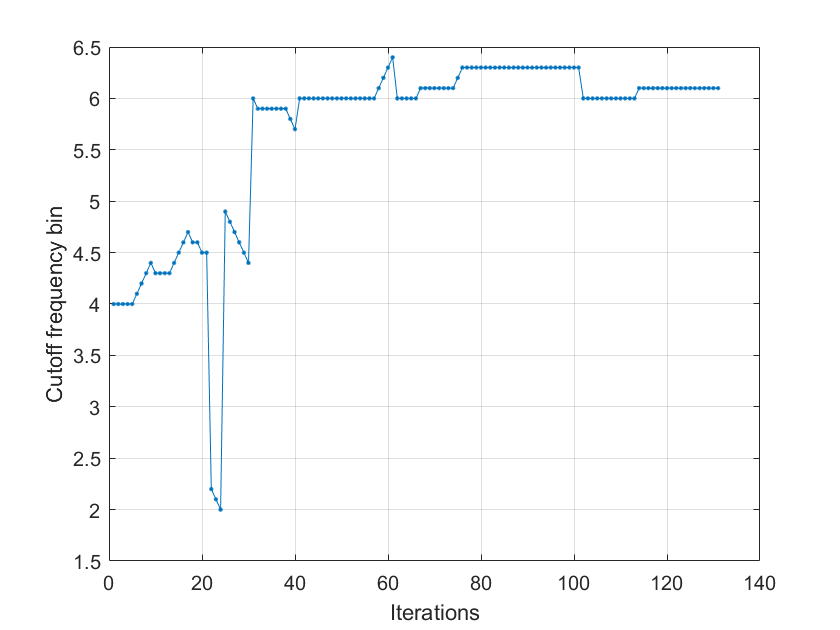


%cutoff frequency bin
figure()
plot(f0_arr,'.-')
ylabel('Cutoff frequency bin')
xlabel('Iterations')
grid on

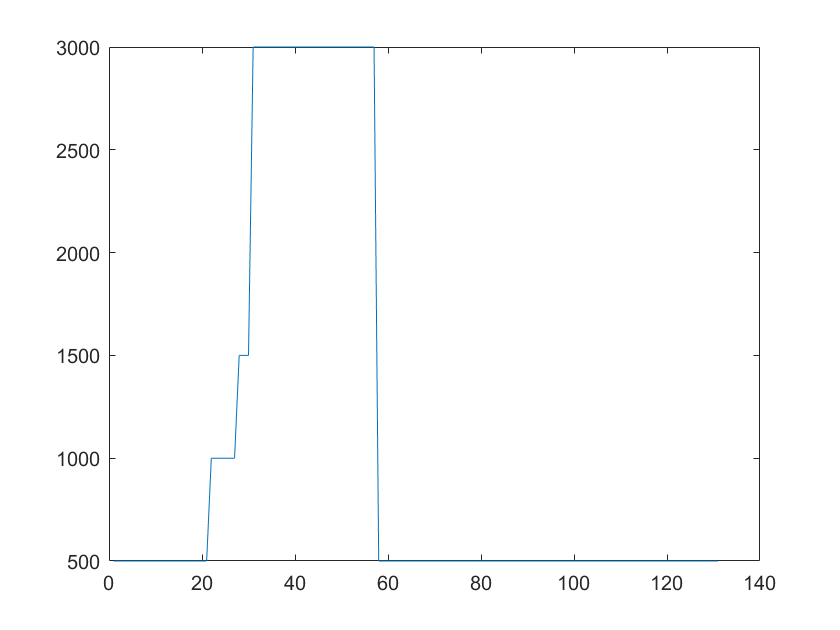


%
figure()
plot(traj_pt_arr)

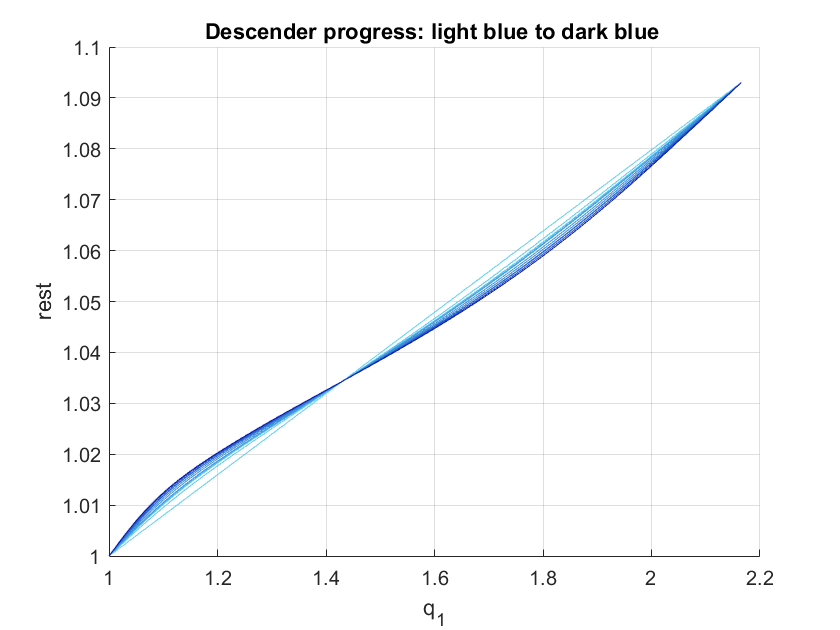


%Trajectories
lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));
diter  = 1;
figure()
hold on
for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    traj = PS_traj(:,1:num_spec);
    plot(traj(:,1),traj(:,2:end),'color',blueGRADIENTflexible(i,tot_iter))
end
xlabel("q_1")
ylabel("rest")
title("Descender progress: light blue to dark blue ")
hold off
grid on

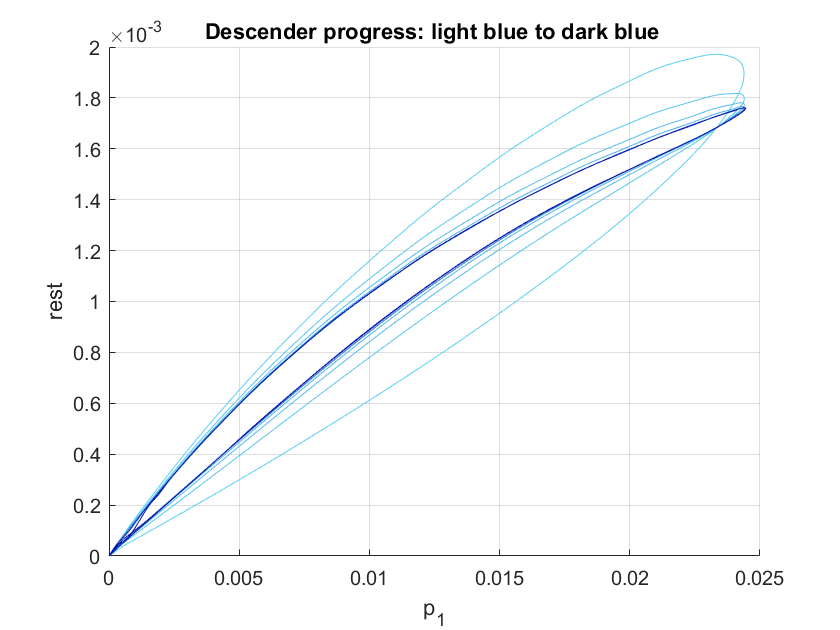

%Trajectories
lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));
diter  = 1;
figure()
hold on
for i = init_iter:diter:tot_iter
    PS_traj = picker_arr_idx(PS_arr,traj_pt_arr,i);
    plot(PS_traj(:,num_spec+1),PS_traj(:,num_spec+2:end),'color',blueGRADIENTflexible(i,tot_iter))
end
xlabel("p_1")
ylabel("rest")
title("Descender progress: light blue to dark blue ")
hold off
grid on

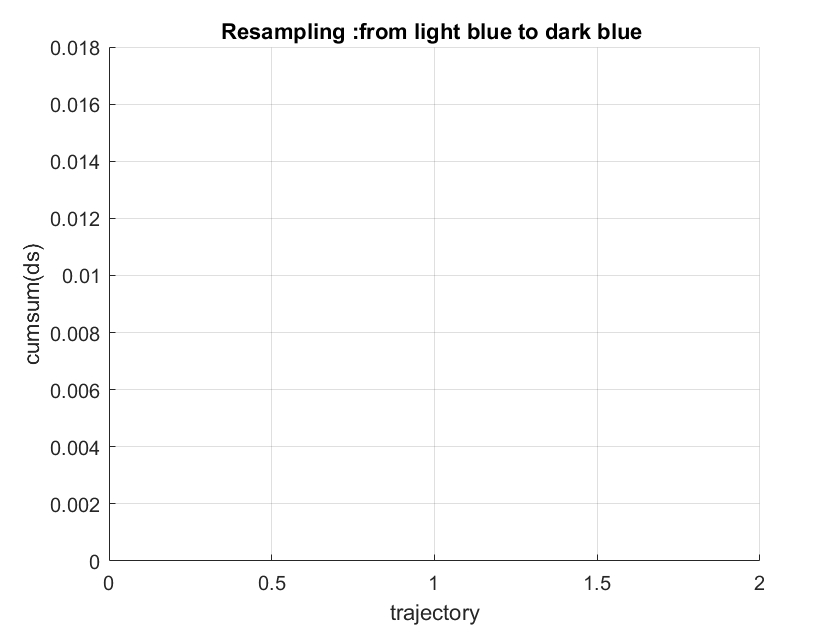


%Surf plots
%Points to skip along trajectory
dtraj = 100;

%resampling array
figure()
hold on
for i = init_iter:tot_iter-1
    plot(s_resamp_arr(i,:),'color',blueGRADIENTflexible(i,tot_iter))
end
xlabel("trajectory")
ylabel("cumsum(ds)")
title("Resampling :from light blue to dark blue ")
hold off
grid on


figure()
surf(s_resamp_arr(:,1:dtraj:traj_pts))

Index in position 2 exceeds array bounds (must not exceed 1).

shading interp
xlabel('iteration')
title('Resampling ')
%view([80 40])



%deltax
traj_pts_indx = 1000;
[deltax_3d, deltax_3d_fft] = surf_input(deltax_arr,num_spec,tot_iter,traj_pt_arr,traj_pts_indx);
[deltax_s_3d, deltax_s_3d_fft] = surf_input(deltax_lp_arr,num_spec,tot_iter,traj_pt_arr,traj_pts_indx);

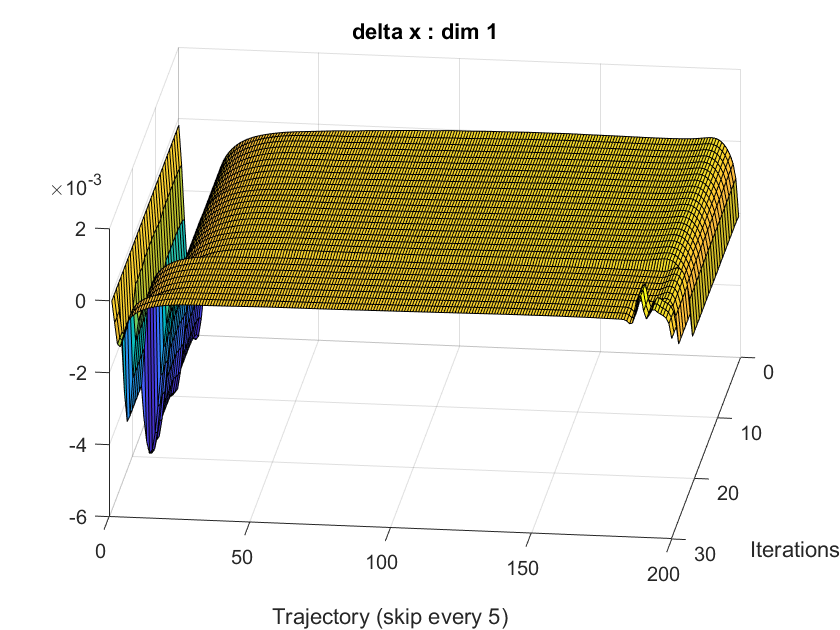

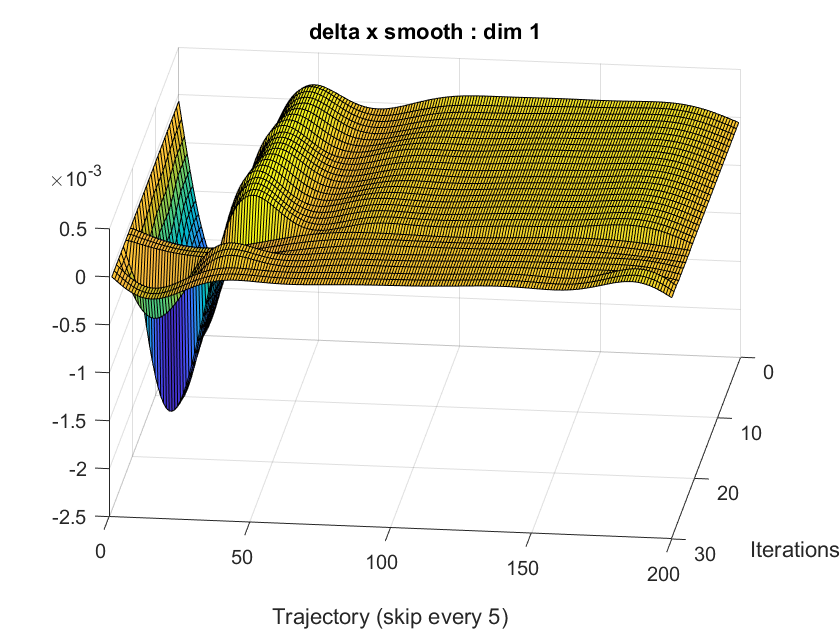

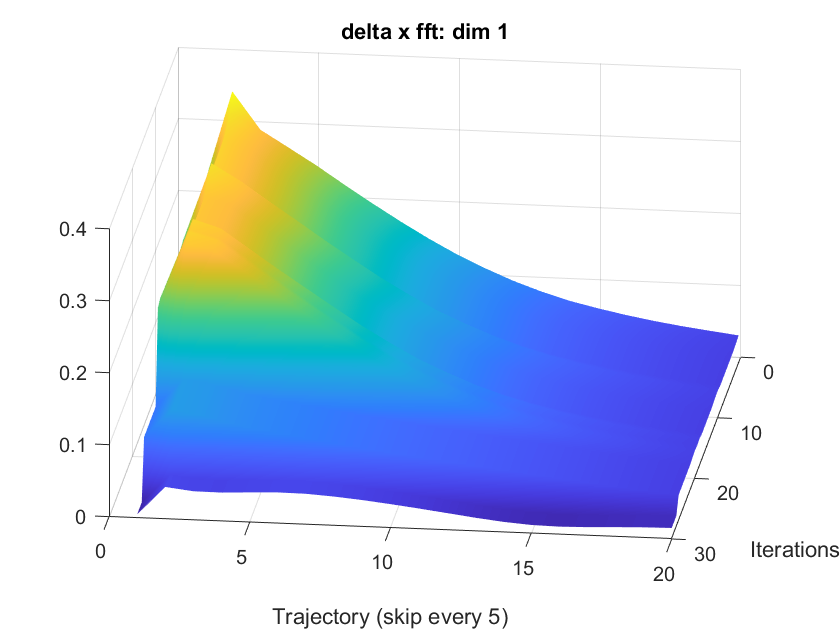

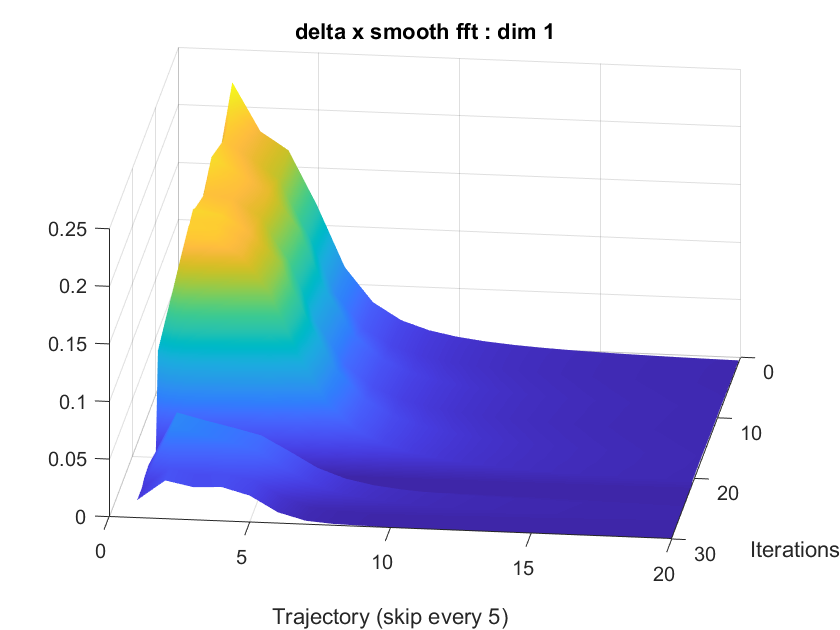

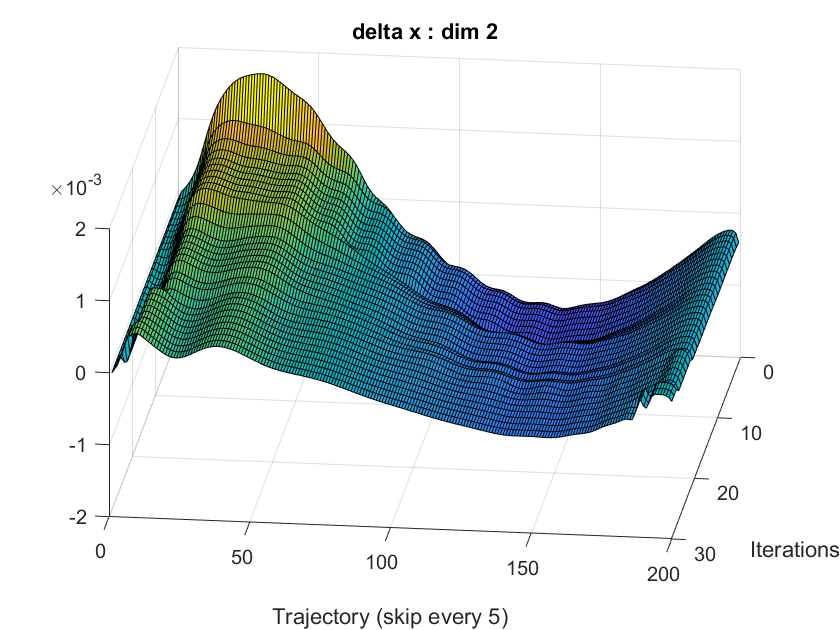

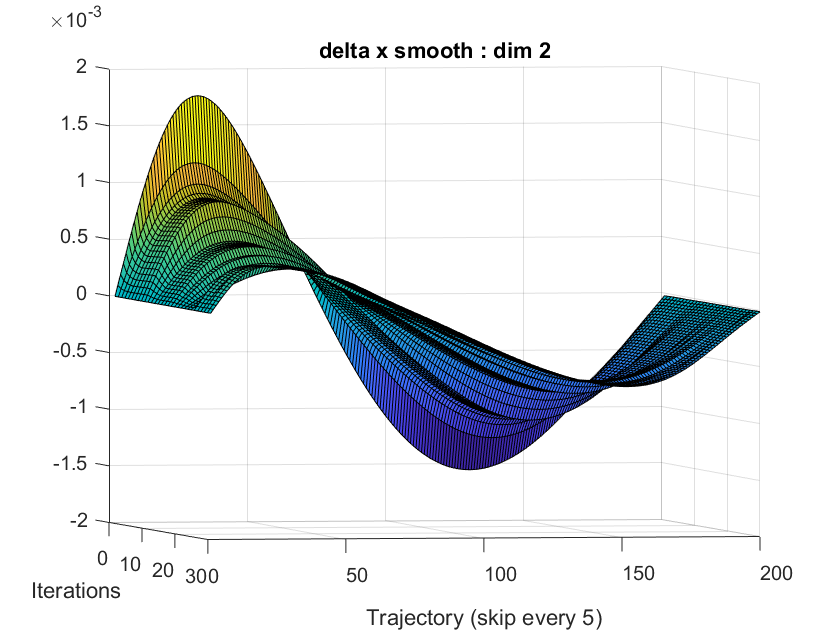

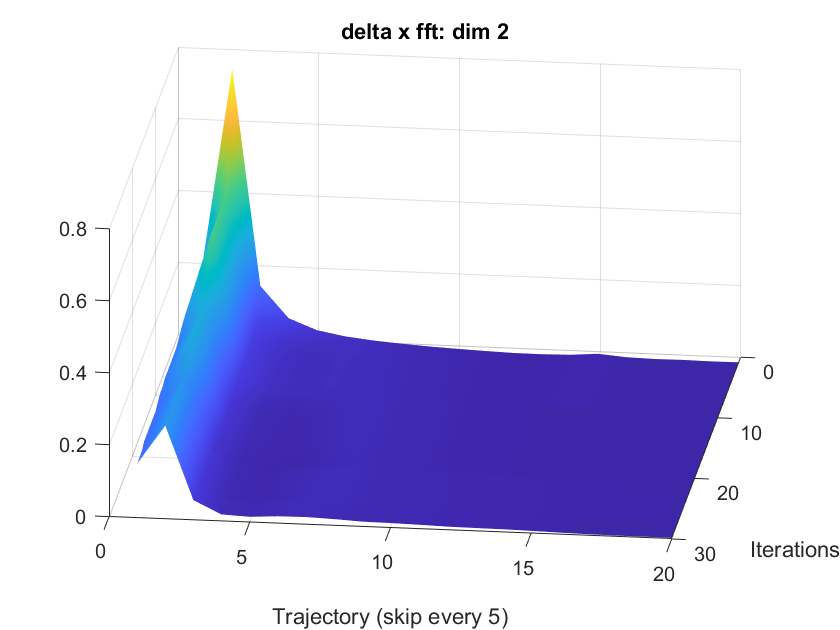

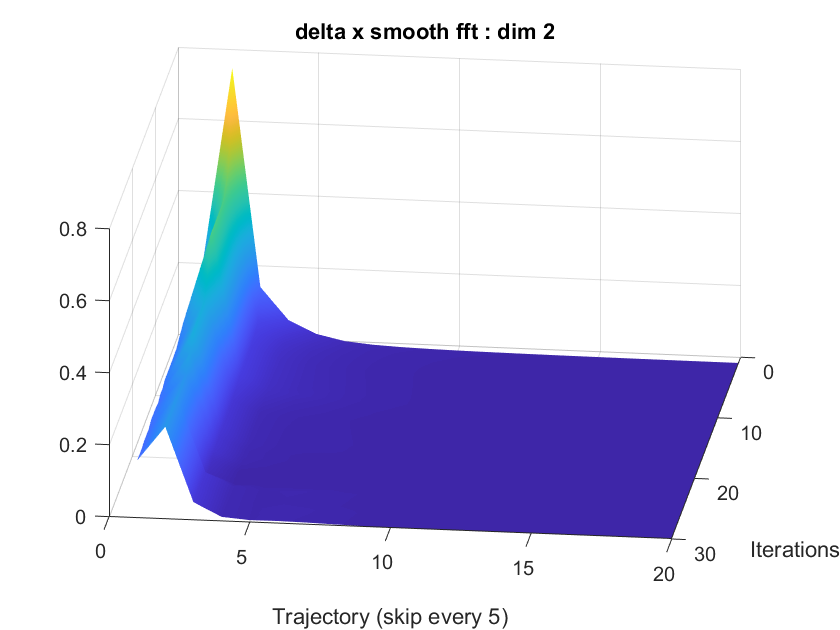

dtraj = 5;
for i = 1:num_spec
    figure()
    surf(squeeze(deltax_3d(i,1:dtraj:traj_pts_indx,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Trajectory (skip every '+string(dtraj)+')')

    figure()
    surf(squeeze(deltax_s_3d(i,1:dtraj:traj_pts_indx,init_iter:diter:tot_iter)))
    %shading interp
    title('delta x smooth : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Trajectory (skip every '+string(dtraj)+')')

    figure()
    surf(squeeze(deltax_3d_fft(i,1:20,init_iter:diter:tot_iter)))
    shading interp
    title('delta x fft: dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Trajectory (skip every '+string(dtraj)+')')

    figure()
    surf(squeeze(deltax_s_3d_fft(i,1:20,init_iter:diter:tot_iter)))
    shading interp
    title('delta x smooth fft : dim '+string(i))
    view([97.02 32.46])
    xlabel('Iterations')
    ylabel('Trajectory (skip every '+string(dtraj)+')')

end

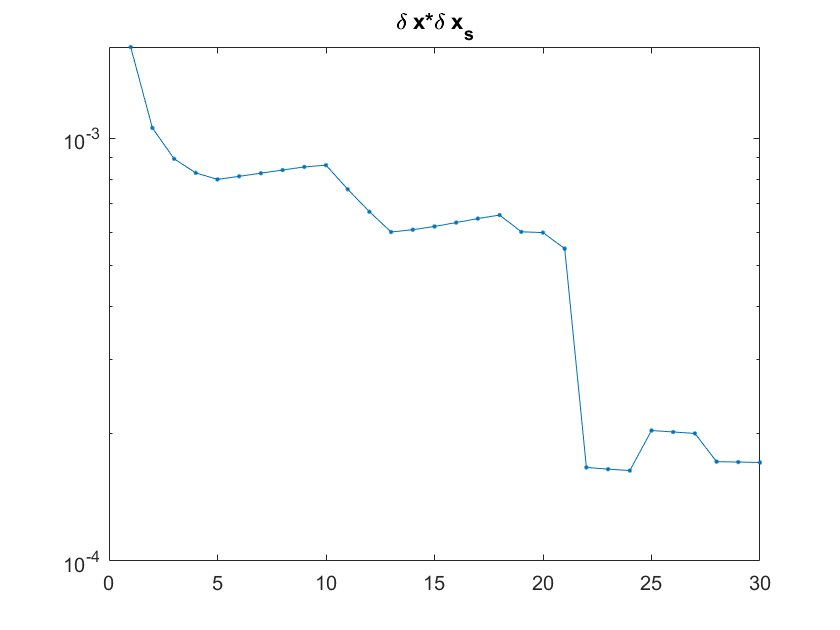


%Plot delta_x^2
delta_S = zeros(tot_iter,1);
for i = 1:tot_iter
    delta_S(i) = sum(squeeze(deltax_3d(:,:,i)).*squeeze(deltax_s_3d(:,:,i)),"all");
end
figure()
semilogy(delta_S,'.-')
title('\delta x*\delta x_s')

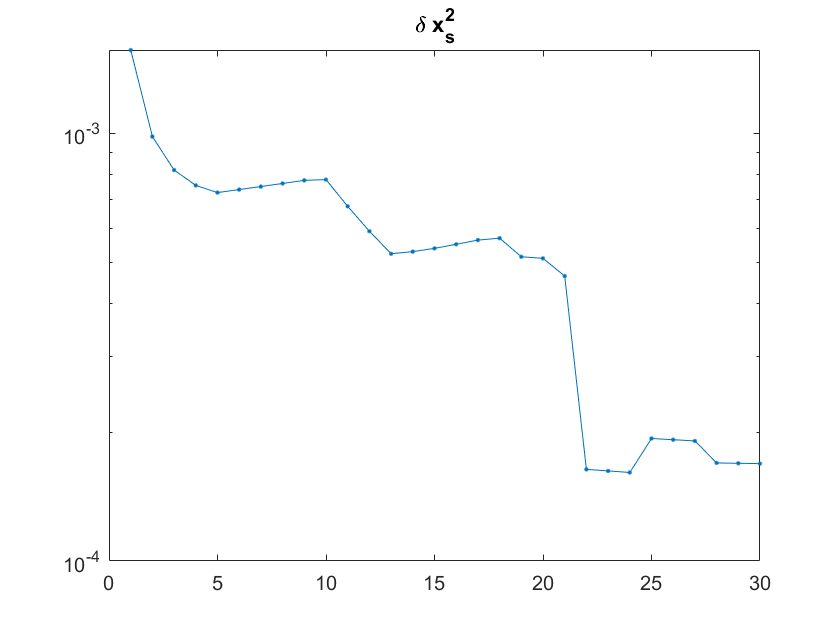


%Plot delta_x_s^2
delta_S = zeros(tot_iter,1);
for i = 1:tot_iter
    delta_S(i) = sum(squeeze(deltax_s_3d(:,:,i)).*squeeze(deltax_s_3d(:,:,i)),"all");
end
figure()
semilogy(delta_S,'.-')
title('\delta x_s^2')

%{

deltax_arr = [deltax_arr; delta_x];
deltax_lp_arr = [deltax_lp_arr; delta_x_s];
time_arr = [time_arr; t_traj'];
S_traj_arr = [S_traj_arr; S_traj'];

s_resamp_arr = [s_resamp_arr; s_resamp'];
%}
